# Brushless motor fundamental

required knowledge :

- magnetics 

- mechanics 

- thermodynamics 

- electronics 

- acostics and

- material sciences

Assumptions :

- Rotational Motion:

- surface mounted magnets

Fundamental Concepts

- mutual toroque

- back EMF

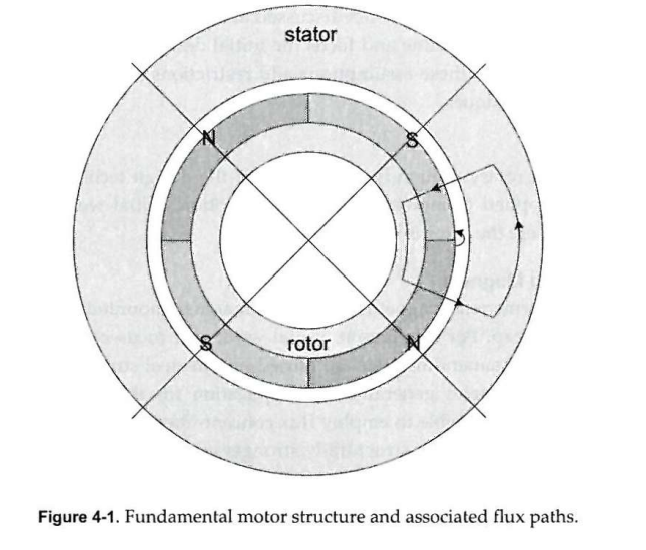

the flux paths repeat for every adajacent half pole pair.

In an enlarged image, this is what supposed to look like .

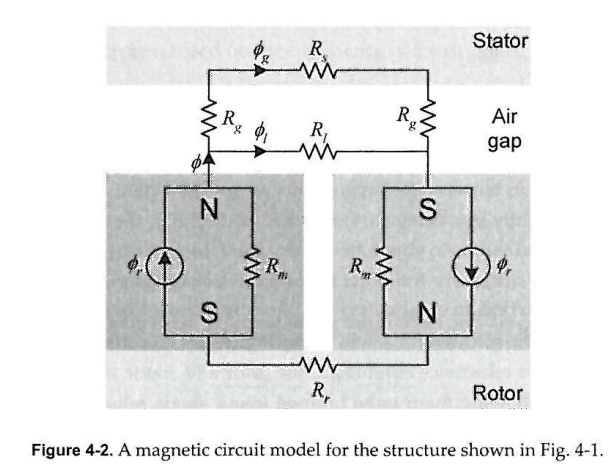

- rotor steel areas and stator steel areas are modeled simply as reluctances Rr and Rs

- The two half magnets are modeled as flux source $\phi_r$and associated amgnet reluctance $R_m$ , with the direction of the flux source dictating the magnet properly.

Before finding a backEMF , the magnetic circuit must be solved to determine the air gap flux density $B_g$

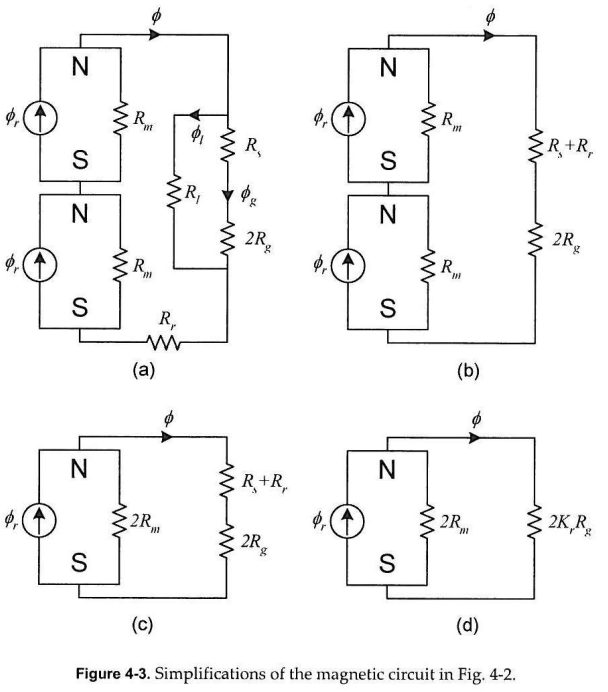

At this point it is difficult to determine an analytical description of the leakage reluactance . 

But

The percentage of flux that travels the primary flux path across the air gap relative to the magnet flux can be estimated .

as $\phi_g =K_l \phi$where $K_l$ is a leakage factor (typically < 1)

so in (b) we can eliminate the leakage reluctance $R_l$ so that we can eliminate the $R_l$ and compensate that with a constant of $K_l$ to obtain $\phi_g$

from c to d, the steel reluctance $R_{r\;} +R_s$is non linear because of the saturation characteristic of ferromagnetic mateirals . Therefore this reluctance must be eliminated in some way to find an analytic solution .

Since the permeability of steel is high relative to air , the reluctance of steel is low relative to air  So we can use another constant $K_r$ to represent the perturbation of the air gap reluctance.

Magnetic Circuit solution 

Using the magnetic circuit in Fig 4-3d, the magnet flux can be expresed using flux division 


$$\phi =\frac{2R_m }{2R_m +2K_r R_g }\phi_r =\frac{1}{1+K_r \left(\frac{R_g }{R_m }\right)}\phi_r$$


Based on $\phi_g =K_l \phi$, and general expressions for the magnet and air gap reluctnace,

$R_{m\;} =\frac{l_m }{\mu_R \mu_0 A_m }$, $R_g =\frac{g}{\mu_0 A_g }$

the air gap flux can be written as 


$$\phi_g =K_l \phi =\frac{1}{1+K_r \left(\frac{\mu_R \mu_0 A_m }{l_m A_g }\right)}\phi_r \;$$


where l_m abd A_m are the magnet length and cross-sectional area respectively. 

With the flux concentration factor $C_{\phi } =\frac{A_m }{A_g }$, 

the flux density relationships $B_g =\frac{\phi_g }{A_g }$and $B_r =\frac{\phi_r }{A_m }$

the permeance coefficienct as $P_c =\frac{l_m }{{\textrm{gC}}_{\phi } }$

gives an air gap flux density of 


$$B_g =\frac{K_l C_{\phi } }{1+K_r \left(\frac{\mu_R }{P_c }\right)}B_r$$



phi_r = ?; 

g = ?; % length of air gap
l_m = ?; % length of magnet

A_g = ?; % cross-sectional area of air gap

N_spp = 1.2500

A_m = ?; % cross sectional area of magnet

theta_s = 24

theta_m = 48

K_l = ?; % leakage factor
K_r = ?; % reluctnace factor
u_R = ?; % relative permeability
P_c = ?; % permeance coefficient



C_phi = A_m / A_g; 
B_r = phi_r / A_m;

B_g = K_l * C_phi / (1 + K_r * u_R/ P_c) * B_r;

generally , 

the leakage factor is between 0.9 to 1.0

relucntace factor is between 1.0 to 1.2.

flux concentration factor is ideally 1.0.

IF considering these values to be fixed and 

the remanence B_r to be fixed by the magnet choice , the permeanace coefficient P_r determines the ** amplitude fo the air gap flux density **.

increase in the permeance coefficient , the air gap density approaches a maximum that is slightly less than the remanence.

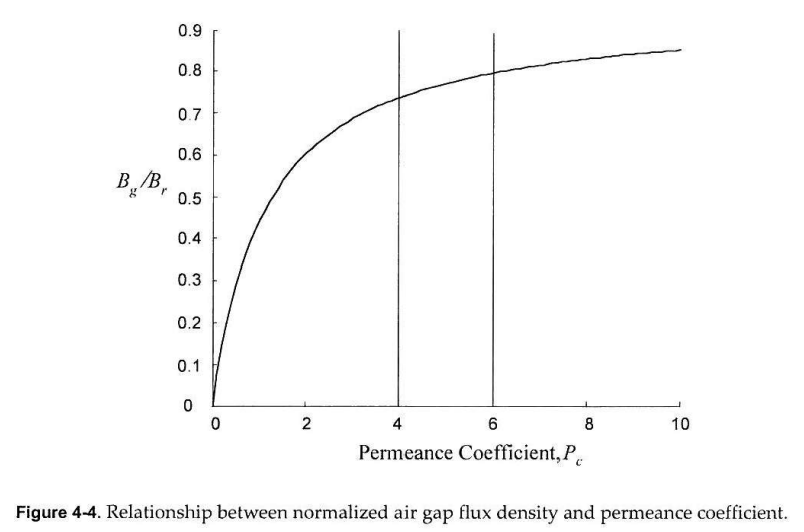

vertical lines mark the typcial four to size permeanace coefficient range used in many motor designs.

Flux Linkage 

How does flux linkage varies with the theta ?

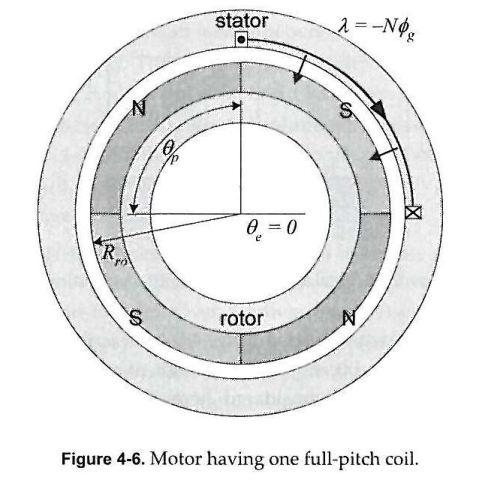

in here the flux flows towards the S pole , the flux flow direction is the opposite of that produced by current flowing in the coil

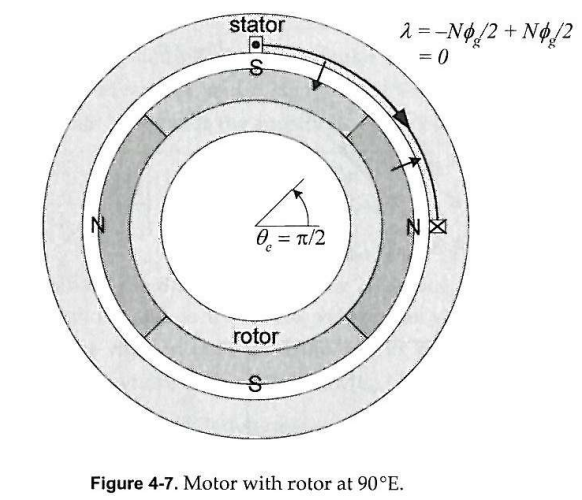

the statos is centered over a half og S and a half of N . The flux cancel out each other hence 0.

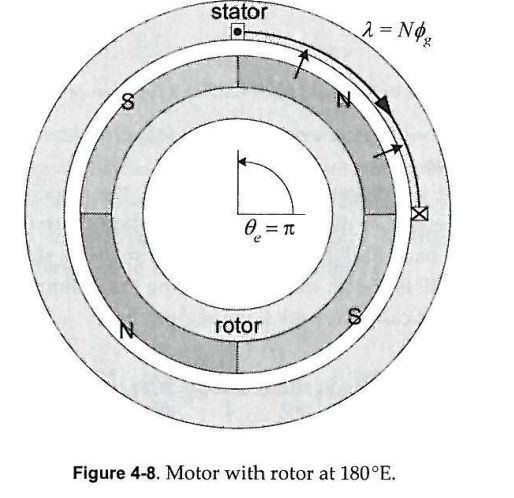

Hence this graph 

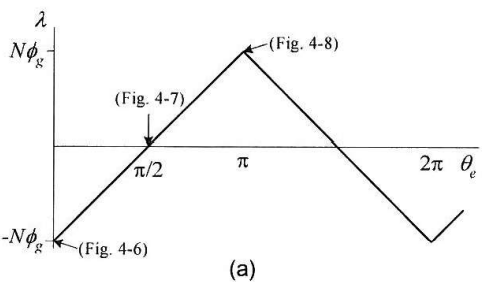

and the associated back EMF is the derivative of the waveform as dictated by Faraday's Law. 


$$e_b =\frac{\partial \lambda }{\partial t}=\frac{\partial \theta_e }{\partial t}\;\frac{\partial \lambda }{\partial \theta_e }=w_e \;\frac{\partial \lambda }{\partial \theta_e }=\frac{N_m }{2}w_m \frac{\partial \lambda }{\partial \theta_e }=\frac{N_m }{2}w_m \;2N\frac{\phi_g }{\pi }$$
 

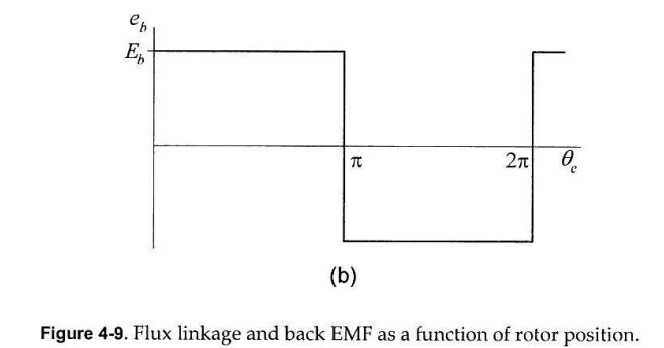


$$\phi_g =B_g A_g =B_g R_{\textrm{ro}} \theta_p L_{\textrm{st}} =\frac{2\pi }{N_m }B_g L_{\textrm{st}} R_{\textrm{ro}}$$


$\theta p$ the angular pole pitch in radM

$R_{\textrm{ro}}$the air gap radius at the magnet surface

$L_{\textrm{st}}$the axial length of the motor

substituting into $e_b$


$$e_b =\frac{N_m }{2}w_m \;2N\frac{\frac{2\pi }{N_m }B_g L_{\textrm{st}} R_{\textrm{ro}} }{\pi }=w_m 2{\textrm{NB}}_g L_{\textrm{st}} R_{\textrm{ro}} =w_{m\;} K_e$$
 

K_e is a constant for that system

The amplitude of the torque 

$T=\frac{E_b i}{w_m }=2{\textrm{NB}}_g L_{\textrm{st}} R_{\textrm{ro}} i=K_t i$ , K_t and K_e are the same

Add two more slots all same phase 

by adding two more, 

the back EMF amplitude cales up to 

 
$$E=w_m 2{\textrm{NB}}_g L_{\textrm{st}} R_{\textrm{ro}} \;2N_m$$
 

and the torque will scale up accordingly

$T=\frac{E_b i}{w_m }=2N_m 2{\textrm{NB}}_g L_{\textrm{st}} R_{\textrm{ro}} i$ but this is when all coils have the same phase

two more slots different phase

each phase will have the same amplitude and frequency 

but delay ro 120 degree E in slot placement

## Fractional pitch coil

the rotor remains unchanges but the coil 

spans an angle of $\theta_c =120\;E$(angular coil pitch), 

$\theta_p$(pole pitch angle)

where the coil pitch factor is defined as $\alpha_c =\frac{\theta_c }{\theta_p }$.

The flux linkage will ne like the graph below

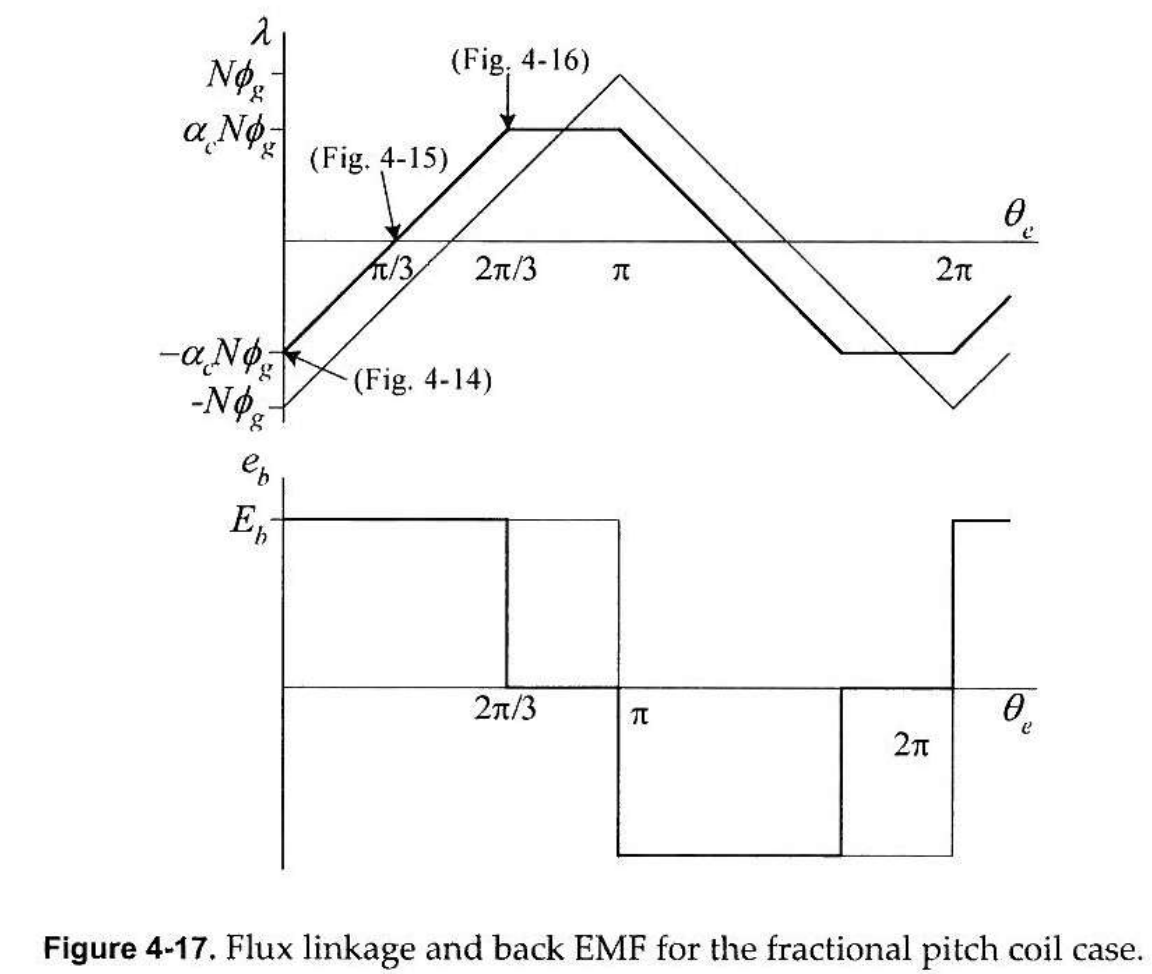

FRAIONAL SLOT MOROT


$$N_{\textrm{spp}} =\frac{N_s }{N_m N_{\textrm{ph}} }$$


N_s = number of slot

N_m = number of magnet pair (poles)

N_ph = 3 phases

if N_spp is an integer , the motor is integral slot motor,

else , it is a fractional slot motor

angular slot pitch is 

$\frac{\;360\;M}{\;N_s }$ , N_s is number of slots


N_s = 15; % slot 
N_m = 4; % magnet poles 
N_ph = 3;  % phase 


N_spp = N_s/N_m/N_ph % slots/pole/phase
theta_s = 360/N_s % angular slot pitch (electrical)
theta_m = theta_s* N_m / 2 % angular slot pitch(mechanical)

coil_spans = 3; % slots
theta_m_sum = coil_spans * theta_m; % totla angular slot pitch



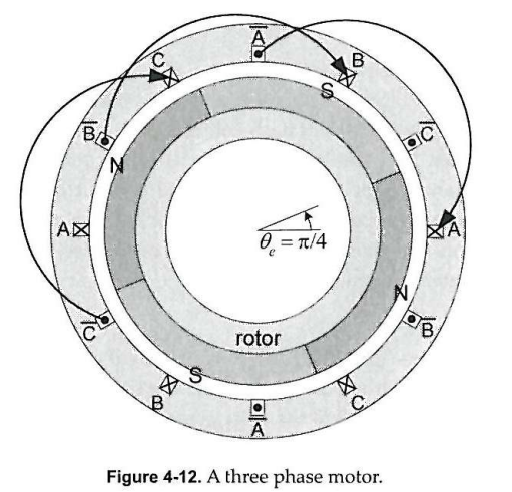

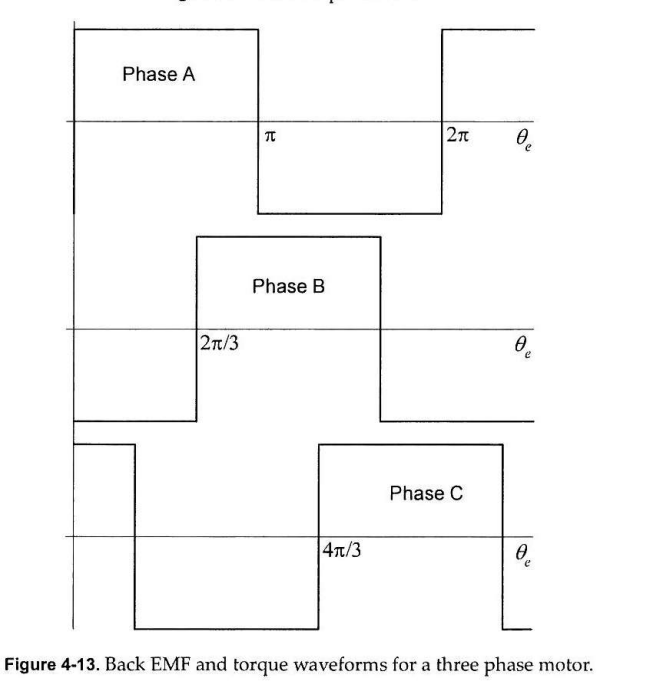

3 phase , the zero crossing of the back EMF and torque are separated by (360) /3 

## Coil Resistance


$$R=\rho \frac{l}{A}$$


p , resistivity of the material in ohm . m 

l ix the material length

A is the cross sectional area

other than that resistivtiy also will plot against Rmeprature 

## Coil Inductance

- mutual inductance exists only consider the inductane in a given phase

- three distinct componenets :

-     air gap 

-      the slots 

-     the end turns

- feeromagnetic portion do not contribute to the inductance as long asrelative permeability is high

- magnet flux does not contribute , the inductances mainly created by the coil current. The magnet are simply blocks of material having relative permeablity 

## Air Gap inductance

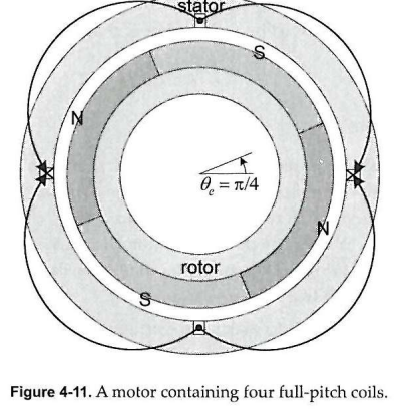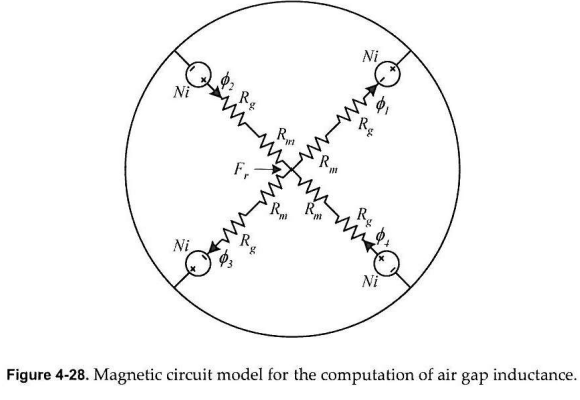

so the arrow is corresponding to S pole and N pole . 


$$\phi_1 -\phi_2 +\phi_3 -\phi_4 =0$$


$\frac{\left(F_r +N_i \right)}{R_g +R_m }-\frac{\left(N_i -F_r \right)}{R_g +R_m }+\frac{\left(F_r +N_i \right)}{\left(R_g +R_m \right)}-\frac{\left(N_i -F_r \right)}{R_g +R_m }=0$ this is sum of fluxes leaving the center node to zero

F_r = 0 


$$\phi_i =\frac{N_i }{R_g +R_m }$$


Therefore


$$\phi_1 =\phi_2 =\phi_3 =\phi_4 =\frac{\textrm{Ni}}{R_g +R_m }$$



$$\lambda =N\left(\phi_1 +\phi_2 +\phi_3 +\phi_4 \right)=\frac{{N^2 \textrm{iN}}_m }{R_g +R_m }$$


Using the definiteion of inductance


$$L_g =\frac{\lambda }{i}=N_m \frac{N^2 }{R_g +R_m }$$


with resistance


$$L_g =\frac{\lambda }{i}=2\pi \mu_o L_{\textrm{st}} R_{\textrm{ro}} \frac{N^2 }{g+\frac{l_m }{\mu_R C_{\phi } }}$$


later this will be modified depending on the parallel or series.

## slot leakage inductance

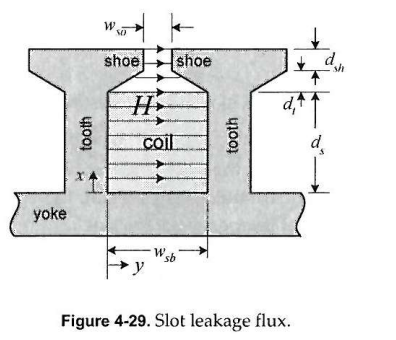

field across the slot when current flowing into the page.

This field is called slot leakage inductance. Computation of this requires more work than caculating the air gap inductance as the magnetic field linking the coil is not constant but linear w.r.t the slot depth.


$$H_y \left(x\right)=\frac{2\textrm{Ni}}{w_{\textrm{sb}} }\frac{x}{d_s }$$


at the bottom , it is x =0 . hence no Hy /

as X increase , more current is enclosed until the max value is reached .

Computing the inductance in this coil are requires using the coenergy relationhsip.

In this case integral over the are agives the coil area leakage inductance $L_{\textrm{ca}} =\mu_0 d_s L_{\textrm{st}} \frac{{\left(2N\right)}^2 }{3w_{\textrm{sb}} }$ where the L_st is the axial length of the slot.

This expression matches with L_ca = N^2 P where P is the effective permeance of the slot

Hence the sum of the coil area:


$$L_{\textrm{st}} ={\left(2N\right)}^2 \left(\mu_o d_s \frac{L_{\textrm{st}} }{3w_{\textrm{sb}} }+\frac{\left(\mu_o d_t L_{\textrm{st}} \right)}{\frac{\left(w_{\textrm{so}} +w_{\textrm{sb}} \right)}{2}}+\frac{\left(\mu_o d_{\textrm{sh}} L_{\textrm{st}} \right)}{w_{\textrm{so}} }\right)$$


first term is the effective permeance of the coil area

the secon is the tapered area

 the last is the permeae of the shor tip area

In full ptich winding 


$$L_s ={N_m \left(2N\right)}^2 \left(\mu_o d_s \frac{L_{\textrm{st}} }{3w_{\textrm{sb}} }+\frac{\left(\mu_o d_t L_{\textrm{st}} \right)}{\frac{\left(w_{\textrm{so}} +w_{\textrm{sb}} \right)}{2}}+\frac{\left(\mu_o d_{\textrm{sh}} L_{\textrm{st}} \right)}{w_{\textrm{so}} }\right)$$


## End Tern Inductance

definition : created by the magnetic field taht surrounds a col after it leaves one slot and before it enters another slot.

The end turns are semicircular with radius equla one half the mean coil pitch $\tau_{\textrm{cp}}$; tje raidus is equal to $\frac{\tau_{\textrm{cp}} }{2}$; and because there are two coils per slotm the end turn bundle has a cross sectional area equal to one half the slot cross-sectional area As.

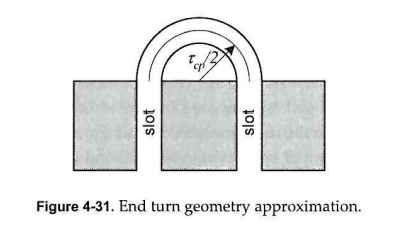


$$L_{\textrm{e1}} =\frac{\mu_o \tau_{\textrm{cp}} N^2 }{4}\ln \left(\frac{\tau_{\textrm{cp}} }{\sqrt{2A_s }}\sqrt{\pi }\right)$$


Since there are 2N_m end turn bundles per phase winding and there is no mutual coupling between the end terns of other coils in the same phase , the toal end turn inductance per phase is 


$$L_{\textrm{e1}} =\frac{{N_m \mu }_o \tau_{\textrm{cp}} N^2 }{4}\ln \left(\frac{\tau_{\textrm{cp}} }{\sqrt{2A_s }}\sqrt{\pi }\right)$$


Total inductance 


$$L_{\textrm{ph}} =L_g +L_s +L_e$$


## Series and Parallel Connection